# FF_VFI_AZ_BISEC_VEC Dynamic Savings Problem Vectorized Continuous Exact

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **This function solves the dynamic programming problem for a (a,z) model. Households can save a, and face AR(1) shock z. The problem is solved over the infinite horizon. This is a vectorized code, it is much faster for larger state-space problems then looped code.

The code uses continuous choices, solved with bi(multi)section. The state-space is on a grid, but choice grids are in terms of percentage of resources available, which is individual specific, to save and solved exactly up to ((1/(2)^16)*100=0.001525878) percentage of cash on hand. THe  [**ff_vfi_az_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_vec.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/) solves the same problem using vectorized common grid code where the choice set and state space share the same grid. 

This is the vectorized code, its speed is much faster than the looped code. The function is designed to have small memory footprint and requires low computing resources, yet is fast.

**Links to Four Code:**

Four Core Savings/Borrowing Dynamic Programming Solution Functions that are functions in the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **:

- Common Choice and States Grid ***Loop***: [**ff_vfi_az_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_loop.m), slow should use for testing new models

- Common Choice and States Grid ***Vectorized***:  [**ff_vfi_az_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_vec.m), fast good for many purposes

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Loop***:[** ff_vfi_az_bisec_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_loop.m), high precision even with small grid

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Vectorized***: [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m), precision and speed

## Test FF_VFI_AZ_BISEC_VEC Defaults

Call the function with defaults. By default, shows the asset policy function summary. Model parameters can be changed by the mp_params.

%mp_params
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('fl_crra') = 1.5;
mp_params('fl_beta') = 0.94;
% call function
ff_vfi_az_bisec_vec(mp_params);

Elapsed time is 0.341348 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
          i    idx    ndim    numel    rowN    colN     sum      mean      std      coefvari    min     max  
          _    ___    ____    _____    ____    ____    _____    ______    ______    ________    ___    ______

    ap    1     1      2       700     100      7      15835    22.621    13.367    0.59091      0     47.273

xxx TABLE:ap xxxxxxxxxxxxxxxxxx
       

## Test FF_VFI_AZ_BISEC_VEC Speed Tests

Call the function with defaults. By default, shows the asset policy function summary. Model parameters can be changed by the mp_params.

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};

A grid 50, shock grid 5:

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
ff_vfi_az_bisec_vec(mp_params, mp_support);

Elapsed time is 0.188450 seconds.


A grid 750, shock grid 15:

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 15;
ff_vfi_az_bisec_vec(mp_params, mp_support);

Elapsed time is 12.017243 seconds.


A grid 600, shock grid 45:

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 600;
mp_params('it_z_n') = 45;
ff_vfi_az_bisec_vec(mp_params, mp_support);

Elapsed time is 22.719622 seconds.


## Test FF_VFI_AZ_BISEC_VEC Control Outputs

Run the function first without any outputs;

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = false;
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;

Run the function and show policy function for savings choice. For ls_ffcmd, ls_ffsna, ls_ffgrh, can include these: 'v', 'ap', 'c', 'y', 'coh', 'savefraccoh'. These are value, aprime savings choice, consumption, income, cash on hand, and savings fraction as cash-on-hand.

Elapsed time is 0.160923 seconds.
xxx  ff_vfi_az_vec, outcome=savefraccoh  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group      a       mean_z_0_54195    mean_z_0_66401    mean_z_0_88162    mean_z_1_3095    mean_z_2_2745
    _____    ______    ______________    ______________    ______________    _____________    _____________

      1           0             0                 0                 0                 0          0.24358   
      2      1.0204       0.33724           0.31063           0.29793           0.32952           0.3998   
      3      2.0408       0.49626           0.47337            0.4572           0.46446          0.49318   
      4      3.0612       0.57912           0.56065            0.5457           0.54484          0.55559   
      5   

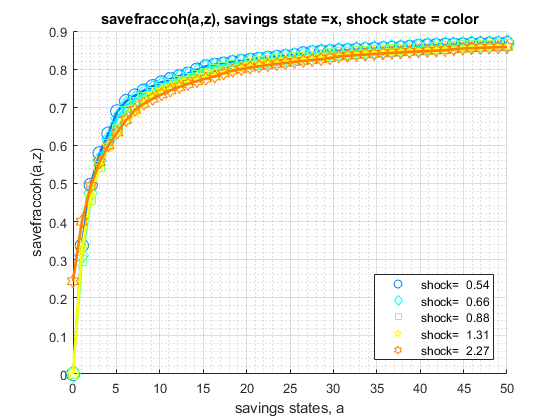

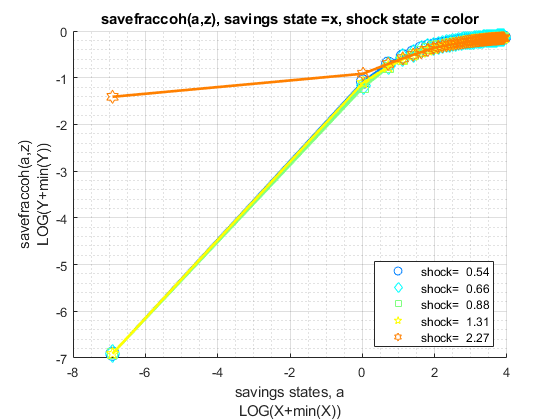

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
% ls_ffcmd: summary print which outcomes
mp_support('ls_ffcmd') = {};
% ls_ffsna: detail print which outcomes
mp_support('ls_ffsna') = {'savefraccoh'};
% ls_ffgrh: graphical print which outcomes
mp_support('ls_ffgrh') = {'savefraccoh'};
ff_vfi_az_bisec_vec(mp_params, mp_support);

Run the function and show summaries for savings and fraction of coh saved:

mp_params('it_a_n') = 100;
mp_params('it_z_n') = 9;
mp_support('ls_ffcmd') = {'ap', 'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_support('bl_vfi_store_all') = true; % store c(a,z), y(a,z)
ff_vfi_az_bisec_vec(mp_params, mp_support);

Elapsed time is 0.443544 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    ap             1     1      2       900     100      9       20493      22.77     13.386     0.5879      0      48.391
 

## Test FF_VFI_AZ_BISEC_VEC Change Interest Rate and Discount

Show only save fraction of cash on hand:

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 9;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Solve the model with several different interest rates and discount factor:

% Lower Savings Incentives
mp_params('fl_beta') = 0.80;
mp_params('fl_r') = 0.01;
ff_vfi_az_bisec_vec(mp_params, mp_support);

Elapsed time is 2.064615 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min     max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    ______

    savefraccoh    1     1      2      6750     750      9      2573.6    0.38127    0.24694    0.64767      0     0.6869

xxx

% Higher Savings Incentives
mp_params('fl_beta') = 0.95;
mp_params('fl_r') = 0.04;
ff_vfi_az_bisec_vec(mp_params, mp_support);

Elapsed time is 8.355503 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      4047.5    0.59963    0.28766    0.47974      0     0.88682



## Test FF_VFI_AZ_BISEC_VEC Changing Risk Aversion

Here, again, show fraction of coh saved in summary tabular form, but also show it graphically.

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {'savefraccoh'};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 9;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Solve the model with different risk aversion levels, higher preferences for risk:

Elapsed time is 6.947134 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      2940.8    0.43567    0.26675    0.61228      0     0.74983



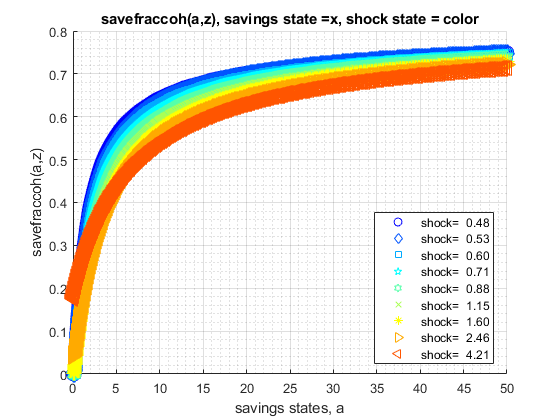

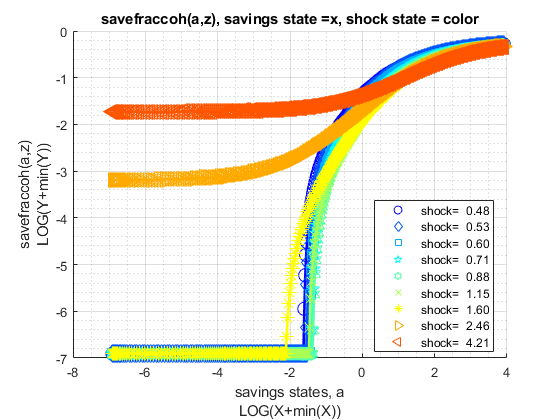

% Lower Risk Aversion
mp_params('fl_crra') = 0.5;
ff_vfi_az_bisec_vec(mp_params, mp_support);

When risk aversion increases, at every state-space point, the household wants to save more.

Elapsed time is 6.425400 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN    sum      mean       std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ____    _______    ______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      4449    0.65911    0.2826    0.42876      0     0.92387

xxx TABLE

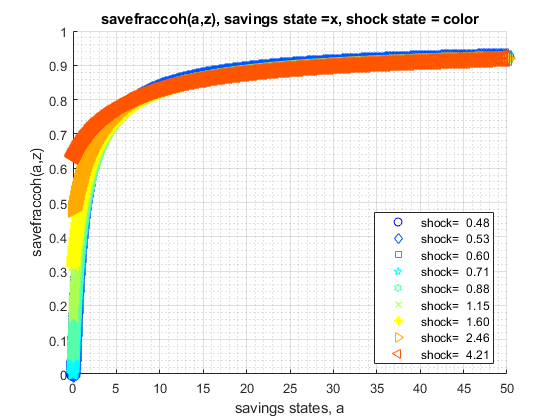

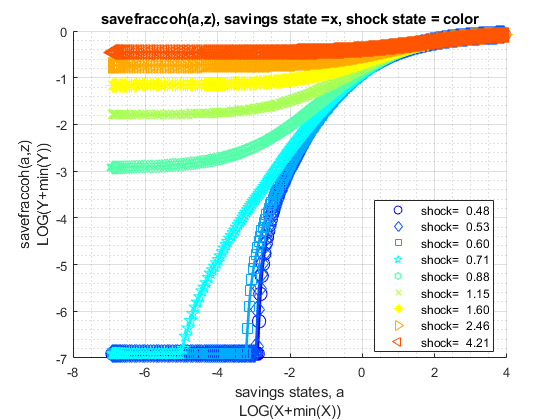

% Higher Risk Aversion
mp_params('fl_crra') = 5;
ff_vfi_az_bisec_vec(mp_params, mp_support);

## Test FF_VFI_AZ_BISEC_VEC with Higher Uncertainty

Increase the standard deviation of the Shock. 

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 9;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Lower standard deviation of shock:

% Lower Risk Aversion
mp_params('fl_shk_std') = 0.10;
ff_vfi_az_bisec_vec(mp_params, mp_support);

Elapsed time is 6.784360 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      3617.7    0.53596    0.31083    0.57996      0     0.86482



Higher shock standard deviation: low shock high asset save more, high shock more asset save less, high shock low asset save more:

% Higher Risk Aversion
mp_params('fl_shk_std') = 0.40;
ff_vfi_az_bisec_vec(mp_params, mp_support);

Elapsed time is 7.804664 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean       std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    ______    _______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      4755.4    0.7045    0.26237    0.37241      0     0.95142

xxx